依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Naive hit miss

预加载此脚本一次即可

TransferLearning.FullCalciumPreload;

排序热图

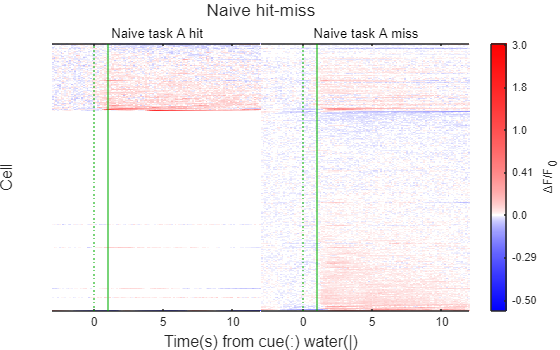

Colors=GlobalOptimization.ColorAllocate(3,[1,1,1;1,1,1]);
Data=MOpNtats.NTATS{:,:,["Naive_cue1_water_hit","Naive_cue1_water_miss"]};
Data=Data(any(Data,2:3),:,:);
Layout=TransferLearning.AucGroupSortedHeatmap(Data,["Naive task A hit","Naive task A miss"],Colors);
title(Layout,'Naive hit-miss');
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print(TransferLearning.ProjectPath('Fig1G.svg'),'-dsvg');